# Development report test bench *Seesaw* - GPAR (UFC)

**Prototype devoloped by: **José Raimundo de Oliveira Júnior

**Report written by: **Douglas Lima Militão Pinheiro

This report presents the activities carried out for the development and use of a prototype available in the laboratory. The system under study exhibits a TISO (two inputs–single output) configuration, in which two motors are used to control the angular position of the main body. The primary objective of this work is to introduce the prototype, describe the development of its mathematical model, and establish a foundation for control design and analysis. As an initial phase of the study, four control strategies are designed and implemented: Proportional–Integral–Derivative (PID), RST (polynomial control), State Feedback (SF), and Feedback Linearization combined with State Feedback (FL+SF). The performance of each control approach is evaluated through dynamic response tests involving both reference tracking and regulation scenarios. Quantitative assessments of control effectiveness are provided using classical performance indices, including the Integral of Absolute Error (IAE), Integral of Squared Error (ISE), Integral of Time-weighted Absolute Error (ITAE), and Integral of Time-weighted Squared Error (ITSE).

## **1. System Model**

The system is inspired in bicopter drone models. This family of drones uses two propellers positionned at the extremities of the main body. The middle of the bar is connected to a rotation-axis, being the tilt angle the system output. Papers have presented control strategies for this system using classical controllers such as PID and state-feedback [ 1 ] [ 2 ]. This work provides a comparison of four techniques: PID, RST, State-feedback and Feedback Linearization plus State-feedback.

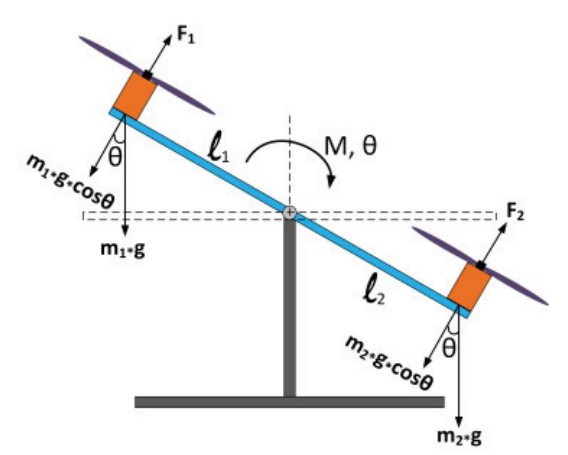

Fig 1. Seesaw system presented in [ 2 ].

The test bench developed for the laboratory uses drone motors as propellers and a potentiometer connected to the rotation center to do the angle measurement as presented in the Figure below.

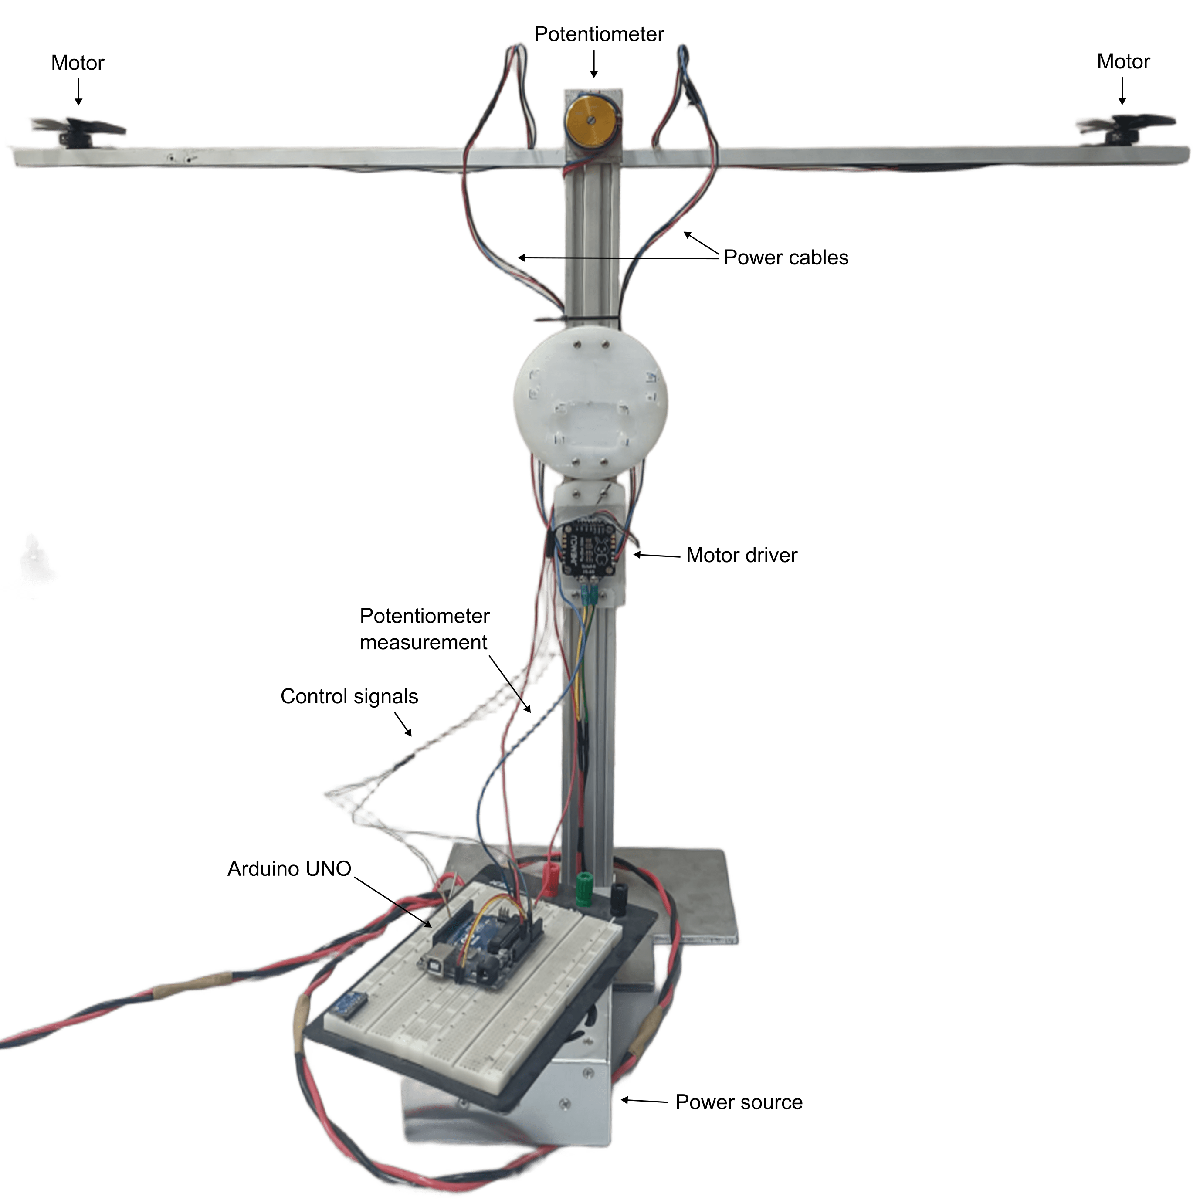

Fig 2. Prototype for experimental tests in laboratory.

The Arduino UNO board is used as interface of the test bench. The algorithms and control laws are developed in the Simulink environnemnt and implemented by using the Connected I/O mode as suggested in [ 3 ]. In this mode the Arduino UNO is used only as interface of inputs and outputs of the test bench, all the signals are processed in the Simulink environnment. This feature is very interesting to bypass the limited power processor of a board like Arduino UNO, allowing the development and experimentation of control laws with high level of complexity. However, it generates some inconvenients, for example it is not possible to adjust the frequency of the PWM signals, then it is necessary an initial analysis of feasibility. 

The following pinout is used to connect the peripherals:

warning('off');

%%%% Pin numbers
pot_pin = 0 %A0 - Potentiometer
motor1 = 9 %D9 - Left Motor
motor2 = 10 %D10 - Right Motor 

%%%% Sampling control task
Ts = 5e-2

%%%% Sampling task potentiometer
Ts_a = Ts

In order to recalculate the angle, there are used the following constants:

%%%% Potentiometer constants
pot_offset = single(512)
pot_gain = single(pi/516)

The rotational speed is calculated by the classical speed definition. A low-pass filter can be used to smooth out the estimation.


$$\frac{\Delta \theta }{\Delta t}=\frac{\Delta \theta }{T_s }$$


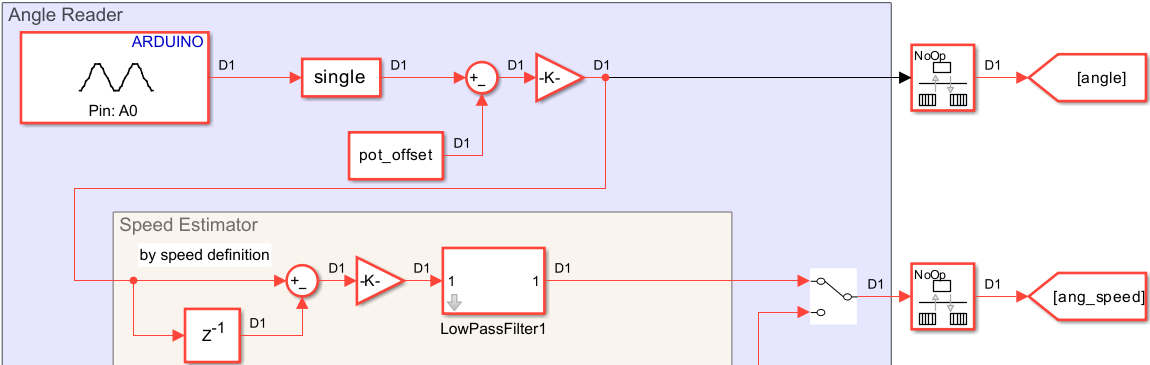

Fig 3. Pre-processing of the potentiometer measurement.

In the same way, a post-processing of the control signal is used for the motor outputs. The driver uses two referenced pulses to control the motor:

- 1 ms for zero velocity

- 2 ms for maximal velocity

Note this is velocity, not torque, and the speed increases almost linearly between these values. The Connected I/O mode forces the output PWM for a frequency of 490.2 Hz. The Simulink block accepts an input between 0 and 255 for zero and maximum dutycyle of the PWM, respectively. The following constants are then defined to linearize an speed reference between 0 and 1 for a value between 0 and 255. To protect the components, it is assumed the maximal speed of the motor as a half of its total range which means 1.5 ms.

%%%% PWM constants
pwm_freq = single(490.2) 
min_dc = (1e-3/(1/pwm_freq))*255
max_dc = (1.5e-3/(1/pwm_freq))*255
pwm_gain = (max_dc-min_dc)


A initialization procedure is necessary to guarantee the driver behaves as expected, there are used these constants:

% Initialization variables
min_dc_init = (1e-3/(1/pwm_freq))*255
max_dc_init = (2e-3/(1/pwm_freq))*255

Note that, they linearize the control of motor speed. Nevertheless, the torque provided by the motors are the inputs of the model. Assuming some simplifications of the driver, as well that time constant of the motor dynamics is much faster than seesaw, the torque can be approximated as:


$$\tau =k_m {\omega_m }^2 \longleftrightarrow \omega_m =\frac{1}{\sqrt{\;k_m }}\sqrt{\tau }$$


Where $k_m$ is a constant linking the motor rotational speed and its torque. For simplicity, this constant is coupled to the gain that relates torque applied by the motor on the system. This means a feedfoward linearization can be applied in the system to bypass this non-linear behavior.

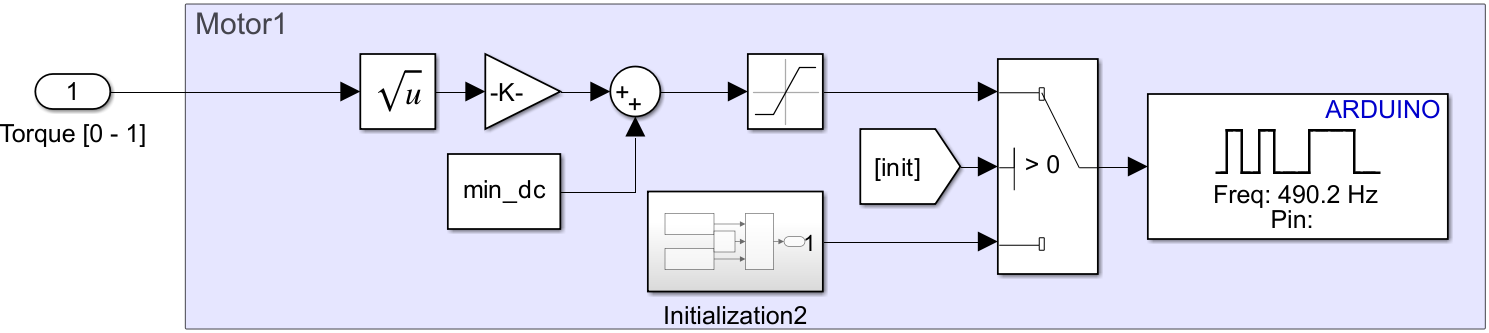

Fig 4. Post-processing of the control signals to generate the PWM wave.

- Obs: It is needed attention in this initialization procedure. Sometimes, for unknown reasons until this moment, this process is not well executed in the *Connected I/O* mode, being necessary the use of the *Run on Board* mode to ensure the configuration of the driver.

Assuming the inputs as the torque provided by the motors ($\tau_x$) and the output as the angle related to the horizontal axis ($\theta$), the system dynamics is described by the following non-linear equation:


$$J\ddot{\theta} =-b\dot{\theta} -\textrm{Mgx}\cdot \sin \left(\theta \right)+G\left(\tau_1 -\tau_2 \right)$$


where:

- $J$ is the system inertia

- $b$ is the dynamic friction coefficient

- $M$is the mass of the system

- $g$ is the gravity constant

- $x$ is the distance between the rotation axis and the gravity center of the system

- $G$ is the gain of the inputs

Nevertheless some coefficients are unknown, experimental tests were carried out to estimate these parameters. The results are illustrated in the following.

%% Model parameters
model.b = 0.25e-1;
model.M = 0.70;
model.L = 0.45;
model.g = 9.81;
model.x = 0.012;
model.J = (model.M*(2*model.L)^2)/12;
model.gain = 0.0016*(model.J)*0.9*10000;

%% Experimental results
load("DataExpe\Ensaio1.mat")
Ts_ensaio = round(mean(diff(Ensaio1.time)),2);
T_sim = Ensaio1.time(end);

%% Model simulation
result = sim("Models\ModelPendulum.slx");

figure
sgtitle("Comparison: Model vs System")
subplot(211)
plot(Ensaio1.time,[result.ensaio_sim.signals.values(:,1) Ensaio1.signals.values(:,3)],LineWidth=1.5)
grid MINOR
legend("Model", "Expe")
xlabel("Time [ s ]")
ylabel("\theta [ rad ]")
subplot(212)
plot(Ensaio1.time,[result.ensaio_sim.signals.values(:,2) Ensaio1.signals.values(:,5)],LineWidth=1.5)
grid MINOR
legend("Model", "Expe")
xlabel("Time [ s ]")
ylabel("\omega [ rad/s ]")

## 2. Linearized system

From the equation presented in the Section 1, a linearized model can be extracted. Assuming:


$$\sin \left(\theta_e +\Delta \theta \right)=\sin \left(\theta_e \right)\cos \left(\Delta \theta \right)+\cos \left(\theta_e \right)\sin \left(\Delta \theta \right)$$


where $\theta_e \;$is the operating point of the system and $\Delta \theta$ is the angle variation around this point. The simplest case is around the angle zero, which means:

  
$$\sin \left(\theta_e +\Delta \theta \right)\approx \;\Delta \theta =\theta$$


The linear model, around zero, is then defined as:


$$\frac{\theta \left(s\right)}{\tau_{1,2} \left(s\right)}=\frac{\pm G}{{\textrm{Js}}^2 +b+\textrm{Mgx}}$$


%%%% Transfer function of the system
tf_model = tf(model.gain,[model.J model.b model.M*model.g*model.x]);

Another way to represent this model is by using the state-space model:

%%%% State space model of the system
ssmodel_A = [0 1; -(model.M*model.g*model.x)/model.J -model.b/model.J];
ssmodel_B = [0 model.gain/model.J; 0 -model.gain/model.J;]';
ssmodel_C = eye(2);
ssmodel_D = 0;
ssmodel = ss(ssmodel_A,ssmodel_B,ssmodel_C,ssmodel_D);

[result_lin,~,~,~] = lsim(ssmodel,Ensaio1.signals.values(:,[1 2]),Ensaio1.time);

figure
sgtitle("Comparison: Model vs System vs Linear Model")
subplot(211)
plot(Ensaio1.time,[result.ensaio_sim.signals.values(:,1) Ensaio1.signals.values(:,3) result_lin(:,1)],LineWidth=1.5)
grid MINOR
legend("Model", "Expe", "Linear Model")
xlabel("Time [ s ]")
ylabel("\theta [ rad ]")
subplot(212)
plot(Ensaio1.time,[result.ensaio_sim.signals.values(:,2) Ensaio1.signals.values(:,5)  result_lin(:,2)],LineWidth=1.5)
grid MINOR
legend("Model", "Expe", "Linear Model")
xlabel("Time [ s ]")
ylabel("\omega [ rad/s ]")

This figure evidences that even with slightly differences of the models and the experimental one, they are similar enough to be considered as representatives of the global behavior for the design of control techniques.

### 2.1 Luenberger Observer

The rotational speed provided by the classical speed definition presents a high noise level which is stressfull for the control loops. The use of low-pass filters produces soften estimations, however it adds delay to the speed measurement. A simple Luenberger observer is then proposed to rebuild the speed waveform. Assuming the angle position as the only available sensor, the system observability is given by:

ssmodel_C = [1 0];
rank(obsv(ssmodel_A, ssmodel_C)) == size(ssmodel_A,1)

The poles of the observer are placed faster than the desired poles of the closed loop dynamics. A trade between velocity and noise amplification was made to choose its values. The place function is used compute the observer gain *L.*

p_observer = [-10 -9]; % s-plane
pd_observer = exp(p_observer*Ts); % z-plane
ssmodel_discrete = c2d(ssmodel,Ts,'zoh');
ssmodel_discrete_A = ssmodel_discrete.A;
ssmodel_discrete_B = ssmodel_discrete.B;

L_gain = place(ssmodel_discrete_A',ssmodel_C',pd_observer)';

%% Model simulation
result = sim("Models\ModelPendulumObserver.slx");

figure
sgtitle("Comparison: Observer vs Estimator")
subplot(3,1,1)
plot(Ensaio1.time,[Ensaio1.signals.values(:,3) result.ensaio_sim.signals.values(:,1) ],LineWidth=1.5)
grid MINOR
legend("Estimator","Observer")
xlabel("Time [ s ]")
ylabel("\theta [ rad ]")
subplot(3,1,[2 3])
plot(Ensaio1.time,[Ensaio1.signals.values(:,5) result.ensaio_sim.signals.values(:,2) ],LineWidth=1.5)
grid MINOR
legend("Estimator","Observer")
xlabel("Time [ s ]")
ylabel("\omega [ rad/s ]")

## 3. Control design

In this section is detailed different control strategies to be applied to this system. The desired closed loop should present a dynamics at least three times faster than the open loop behavior and an overshoot of no more than 5%.

qsi = 1;
tr = stepinfo(tf_model).SettlingTime/6;
wn = 4.74/tr;

tf_cl_model = tf(wn^2,[1 2*qsi*wn wn^2]);

figure
step(tf_model,tf_cl_model);
grid MINOR
title("Open and Closed Loop dynamics")
legend("OL","CL")
ylabel("\theta [ rad ]")

### 3.2 Classical discrete PID

The classical approach of a PID does not take into account the internal dynamics of the system. A equivalent input ($\tau$) is assumed for this strategy, where:


$$\tau =\tau_1 -\tau_2$$


with the equilibrium point with $\tau_1 =\tau_2 =0$. This means for positive values of torque are provided by the motor 1, whilst the motor 2 remains inactive and negatives values of torque is provided by the motor 2, while the first is desactivated. The transfer function is then simplified for a second order system, given by:

 
$$\frac{\theta \left(s\right)}{\tau \left(s\right)}=\frac{\frac{G}{J}}{s^2 +\frac{b}{J}+\frac{\textrm{Mgx}}{J}}$$


The PID controller for this type of system is already known in the literature. A discrete filtered PID is proposed with the gains calculated by:


$$C\left(z^{-1} \right)=\frac{r_0 +r_1 z^{-1} +r_2 z^{-2} }{\left(1-z^{-1} \right)\left(1+s_1 z^{-1} \right)}$$


tf_model_dis = c2d(tf_model,Ts,'zoh');

[num,den] = tfdata(tf_model_dis,'v');
[~,den_mf] = tfdata(c2d(tf(wn^2,[1 2*qsi*wn wn^2]),Ts,'zoh'),'v');

b1 = num(2);
b2 = num(3);
a1 = den(2);
a2 = den(3);
p1 = den_mf(2);
p2 = den_mf(3);

r0_meq = (1+p1+p2)/(b1+b2);
r1_meq = a1*r0_meq;
r2_meq = a2*r0_meq;
s1_meq = r0_meq*b2-p2;

### 3.3 RST 2-DOF

The RST controller is widely used to control discrete SISO systems due to its flexibility to handle with high order systems. It allows the designer to impose different dynamics for tracking and regulation, as well in function of the system complexity to do a pre-caracterization of the controller to handle with disturbances known by the user.

For this case, only the pre-caracterization of the S polynom is used for null-error in steady-state. The tracking dynamics is assumed as the same in the PID controller and the regulation dynamics at least 3 times faster than it. The gain of the controller are then defined:

%%%% Tracking
[num_mf_track,den_mf_track] = tfdata(c2d(tf_cl_model,Ts,'zoh'),'v');

%%%% Regulation

qsi = 0.7;
tr = stepinfo(tf_cl_model).SettlingTime/3;
wn = 2.9/tr;
[~,den_mf] = tfdata(c2d(tf(wn^2,[1 2*qsi*wn wn^2]),Ts,'zoh'),'v');

Pz_RST = den;
    
Sp_RST = [1 -1];
Rp_RST = 1;
    
Cz_RST = conv(den,Sp_RST)';      
Ez_RST = conv(num,Rp_RST)';    % 
nc_RST = length(Cz_RST)-1;          %
ne_d_RST = length(Ez_RST)-1;        %
ns_RST = ne_d_RST - 1;              % 
nr_RST = nc_RST - 1;                %
np_RST = nc_RST + ne_d_RST - 1;     %


M_RST = [];
for i = 1:ns_RST+1
    M_RST = [M_RST [zeros(i-1,1);Cz_RST;zeros(ns_RST-i+1,1)]];
end
for i = 1:nr_RST+1
    M_RST = [M_RST [zeros(i-1,1);Ez_RST(1:end);zeros(nr_RST-i+1,1)]];
end

M_RST;

P_RST = conv(den_mf, Pz_RST);
alpha = 0.05;
Pa_RST = [1 -alpha];
for i = 1:(np_RST-length(P_RST)+1)
    P_RST = conv(Pa_RST, P_RST);
end

P_RST';

X_RST = M_RST\P_RST';
D_RST = X_RST(1:ns_RST+1)';
F_RST = X_RST(ns_RST+2:end)';
S = conv(Sp_RST,D_RST)
R = conv(F_RST,Rp_RST)
T = P_RST/sum(num)

### 3.4 State-feedback

The state-feedback control consists in use all the state informations to calculate the control signal, in this case the angle and the rotational speed. Aiming the disturbances rejection and null-error in the steady-state zone, the extended-model is implemented:

ssmodel_discrete_A_ext = [ssmodel_discrete.A zeros(size(ssmodel_discrete.A,2),1); [-Ts 0 1]]
ssmodel_discrete_B_ext = [ssmodel_discrete.B; [0 0]]

Two approaches can be used to compute the parameter of the controller: the pole placement ou LQR technique. For the first one, the designer imposes the desired dynamics in closed loop, while for the last one a cost function is minimized to computed the optimal gains. In order to compare the closed loop dynamics with the other techniques, this work uses the pole placement.

poles = pole(tf_cl_model);
p_cl = [poles(1) poles(1)*2 poles(1)*3]*1; % s-plane
pd_cl = exp(p_cl*Ts); % z-plane

K_controller = place(ssmodel_discrete_A_ext,ssmodel_discrete_B_ext,pd_cl)

### 3.5 Feedback linearization with state-feedback

The feedback linearization consists in the use of the inverse of the model to obtain a system built of a chains of integrators. This approach is highly dependent on the model and needs to be associated to another strategy to close the control loop, in this case an state-feedback. For this model, the feedback linearization is done by imposing a control law in the form:


$$\tau_{1,2} =\pm \frac{J}{G}\left(\frac{b}{J}\omega +\frac{\textrm{Mgx}}{J}\sin \left(\theta \right)+w_{1,2} \right)$$


The linearized system is then described by:


$$\left\lbrack \begin{array}{c}
\dot{\theta} \\
\dot{\omega} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\theta \\
\omega 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
1 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
w_1 \\
w_2 
\end{array}\right\rbrack$$


The matrices in the continuous representation are:

ssmodel_lin_A = [0 1; 0 0];
ssmodel_lin_B = [0 1; 0 1]';
ssmodel_lin_C = [1 0];
ssmodel_lin_D = 0;

ss_model_lin_dis = c2d(ss(ssmodel_lin_A,ssmodel_lin_B,ssmodel_lin_C,ssmodel_lin_D),Ts,'zoh');
ssmodel_lin_discrete_A_ext = [ss_model_lin_dis.A zeros(size(ss_model_lin_dis.A,2),1); [-Ts 0 1]]
ssmodel_lin_discrete_B_ext = [ss_model_lin_dis.B; [0 0]]
poles = pole(tf_cl_model);
p_cl = [poles(1) poles(1)*2 poles(1)*3]*1; % s-plane
pd_cl = exp(p_cl*Ts); % z-plane

K_controller2 = place(ssmodel_lin_discrete_A_ext,ssmodel_lin_discrete_B_ext,pd_cl)

## 4. Results comparison

### 4.1 Comparison factors

In order to compare the results in simulation and experimental, four factors proposed by [ 4 ] are used. The integral operators are replaced by the equivalent operator in the discrete-time domain, the sum.

IAE - Integral of Absolute Error


$$\textrm{IAE}=\int_0^{\infty } |e\left(t\right)|\textrm{dt}\approx \left(\sum_{k=0}^{\infty } e\left(k\right)\right)\Delta T$$


ISE - Integral of Squared Error


$$\textrm{ISE}=\int_0^{\infty } |e\left(t\right)|^2 \textrm{dt}\approx \left(\sum_{k=0}^{\infty } {e\left(k\right)}^2 \right)\Delta T$$


ITAE - Integral of Time-weighted Absolute Error


$$\textrm{ITAE}=\int_0^{\infty } t|e\left(t\right)|\textrm{dt}\approx \left(\sum_{k=0}^{\infty } t\left(k\right)e\left(k\right)\right)\Delta T$$


ITSE - Integral of Time-weighted Squared Error


$$\textrm{ITSE}=\int_0^{\infty } |e\left(t\right)|\textrm{dt}\approx \left(\sum_{k=0}^{\infty } t\left(k\right){e\left(k\right)}^2 \right)\Delta T$$


### 4.2 Simulation

The simulation uses the non-linear model of the system. This test was implemented in order to compare the closed loop dynamics of each controller for tracking and regulation. The setpoints were placed in $20\mathrm{º}\;\left(0\ldotp 349\;\textrm{rad}\right),-45\mathrm{º}\;\left(-0\ldotp 785\;\textrm{rad}\right)$ and $\textrm{80º}\left(1\ldotp 396\;\textrm{rad}\right)$ and at 20 and 35 s, a disturbance in a step format with amplitude of 0.04 were applied in the control signals.

control = 1;
result_pid = sim("Models\ModelPendulumTest.slx");
control = 2;
result_rst = sim("Models\ModelPendulumTest.slx");
control = 3;
result_sf = sim("Models\ModelPendulumTest.slx");
control = 4;
result_lin_sf = sim("Models\ModelPendulumTest.slx");

figure
sgtitle("Comparison of control techniques")
subplot(411)
plot(result_pid.ensaio_sim.time,[result_pid.ensaio_sim.signals.values(:,2) result_rst.ensaio_sim.signals.values(:,2) result_sf.ensaio_sim.signals.values(:,2) result_lin_sf.ensaio_sim.signals.values(:,2)],LineWidth=1.5)
hold on
plot(result_pid.ensaio_sim.time,result_pid.ensaio_sim.signals.values(:,1),'--',LineWidth=0.5)
hold off
grid MINOR
legend("PID","RST","SF","FL+SF","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("\theta [ rad ]")
subplot(412)
plot(result_pid.ensaio_sim.time,[result_pid.ensaio_sim.signals.values(:,3) result_rst.ensaio_sim.signals.values(:,3) result_sf.ensaio_sim.signals.values(:,3) result_lin_sf.ensaio_sim.signals.values(:,3)],LineWidth=1.5)
grid MINOR
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
ylabel("\omega [ rad/s ]")
subplot(413)
plot(result_pid.ensaio_sim.time,[result_pid.ensaio_sim.signals.values(:,4) result_rst.ensaio_sim.signals.values(:,4) result_sf.ensaio_sim.signals.values(:,4) result_lin_sf.ensaio_sim.signals.values(:,4)],LineWidth=1.5)
grid MINOR
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 1")
ylim([-0.01 0.3])
subplot(414)
plot(result_pid.ensaio_sim.time,[result_pid.ensaio_sim.signals.values(:,5) result_rst.ensaio_sim.signals.values(:,5) result_sf.ensaio_sim.signals.values(:,5) result_lin_sf.ensaio_sim.signals.values(:,5)],LineWidth=1.5)
grid MINOR
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 2")
ylim([-0.01 0.3])

These results evidence that in simulation all controllers have similar tracking behavior as expected, with differences in the regulation dynamics. All of them are able to follow the references of angle and to reject disturbances on the control signals.

%%%% Calcul of the comparison factors

iae_pid_sim = cumsum(abs(result_pid.ensaio_sim.signals.values(:,1) - result_pid.ensaio_sim.signals.values(:,2)))*mean(diff(result_pid.ensaio_sim.time));
ise_pid_sim = cumsum((result_pid.ensaio_sim.signals.values(:,1) - result_pid.ensaio_sim.signals.values(:,2)).^2)*mean(diff(result_pid.ensaio_sim.time));
itae_pid_sim = cumsum(abs(result_pid.ensaio_sim.signals.values(:,1) - result_pid.ensaio_sim.signals.values(:,2)).*result_pid.ensaio_sim.time)*mean(diff(result_pid.ensaio_sim.time));
itse_pid_sim = cumsum(result_pid.ensaio_sim.time.*(result_pid.ensaio_sim.signals.values(:,1) - result_pid.ensaio_sim.signals.values(:,2)).^2)*mean(diff(result_pid.ensaio_sim.time));

iae_rst_sim = cumsum(abs(result_rst.ensaio_sim.signals.values(:,1) - result_rst.ensaio_sim.signals.values(:,2)))*mean(diff(result_rst.ensaio_sim.time));
ise_rst_sim = cumsum((result_rst.ensaio_sim.signals.values(:,1) - result_rst.ensaio_sim.signals.values(:,2)).^2)*mean(diff(result_rst.ensaio_sim.time));
itae_rst_sim = cumsum(abs(result_rst.ensaio_sim.signals.values(:,1) - result_rst.ensaio_sim.signals.values(:,2)).*result_rst.ensaio_sim.time)*mean(diff(result_rst.ensaio_sim.time));
itse_rst_sim = cumsum(result_rst.ensaio_sim.time.*(result_rst.ensaio_sim.signals.values(:,1) - result_rst.ensaio_sim.signals.values(:,2)).^2)*mean(diff(result_rst.ensaio_sim.time));

iae_sf_sim = cumsum(abs(result_sf.ensaio_sim.signals.values(:,1) - result_sf.ensaio_sim.signals.values(:,2)))*mean(diff(result_sf.ensaio_sim.time));
ise_sf_sim = cumsum((result_sf.ensaio_sim.signals.values(:,1) - result_sf.ensaio_sim.signals.values(:,2)).^2)*mean(diff(result_sf.ensaio_sim.time));
itae_sf_sim = cumsum(abs(result_sf.ensaio_sim.signals.values(:,1) - result_sf.ensaio_sim.signals.values(:,2)).*result_sf.ensaio_sim.time)*mean(diff(result_sf.ensaio_sim.time));
itse_sf_sim = cumsum(result_sf.ensaio_sim.time.*(result_sf.ensaio_sim.signals.values(:,1) - result_sf.ensaio_sim.signals.values(:,2)).^2)*mean(diff(result_sf.ensaio_sim.time));

iae_lin_sf_sim = cumsum(abs(result_lin_sf.ensaio_sim.signals.values(:,1) - result_lin_sf.ensaio_sim.signals.values(:,2)))*mean(diff(result_lin_sf.ensaio_sim.time));
ise_lin_sf_sim = cumsum((result_lin_sf.ensaio_sim.signals.values(:,1) - result_lin_sf.ensaio_sim.signals.values(:,2)).^2)*mean(diff(result_lin_sf.ensaio_sim.time));
itae_lin_sf_sim = cumsum(abs(result_lin_sf.ensaio_sim.signals.values(:,1) - result_lin_sf.ensaio_sim.signals.values(:,2)).*result_lin_sf.ensaio_sim.time)*mean(diff(result_lin_sf.ensaio_sim.time));
itse_lin_sf_sim = cumsum(result_lin_sf.ensaio_sim.time.*(result_lin_sf.ensaio_sim.signals.values(:,1) - result_lin_sf.ensaio_sim.signals.values(:,2)).^2)*mean(diff(result_lin_sf.ensaio_sim.time));


figure
sgtitle("Comparison factors (Simulation case)")
subplot(221)
plot(result_pid.ensaio_sim.time,[iae_pid_sim iae_rst_sim iae_sf_sim iae_lin_sf_sim],LineWidth=1.5);
title("IAE")
legend("PID","RST","SF","FL+SF",Location="northwest")
grid MINOR
xlabel("Time [ s ]")
subplot(222)
plot(result_pid.ensaio_sim.time,[ise_pid_sim ise_rst_sim ise_sf_sim ise_lin_sf_sim],LineWidth=1.5);
title("ISE")
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
grid MINOR
subplot(223)
plot(result_pid.ensaio_sim.time,[itae_pid_sim itae_rst_sim itae_sf_sim itae_lin_sf_sim],LineWidth=1.5);
title("ITAE")
legend("PID","RST","SF","FL+SF",Location="northwest")
grid MINOR
xlabel("Time [ s ]")
subplot(224)
plot(result_pid.ensaio_sim.time,[itse_pid_sim itse_rst_sim itse_sf_sim itse_lin_sf_sim],LineWidth=1.5);
title("ITSE")
legend("PID","RST","SF","FL+SF",Location="northwest")
grid MINOR
xlabel("Time [ s ]")

The comparison factors reveal a superiority of the approaches that use the internal states do calculate the control signals (SF and FL+SF). 

### 4.3 Experimental

For the experimental tests is used the file called "ArduinoGPIO2" to execute. In the same manner the reference was imposed the same as the simulation case with disturbances in the control signals. The results were stored in ".mat" files for each controller.

load("DataExpe\Ensaio_lin_sf.mat")
load("DataExpe\Ensaio_sf.mat")
load("DataExpe\Ensaio_pid.mat")
load("DataExpe\Ensaio_rst.mat")

Ensaio_lin_sf.signals.values(1:find(Ensaio_pid.time>=15,1),3) = 0;
Ensaio_sf.signals.values(1:find(Ensaio_pid.time>=15,1),3) = 0;
Ensaio_rst.signals.values(1:find(Ensaio_pid.time>=15,1),3) = 0;
Ensaio_pid.signals.values(1:find(Ensaio_pid.time>=15,1),3) = 0;

figure
sgtitle("Comparison of control techniques")
subplot(411)
plot(Ensaio_pid.time,[Ensaio_pid.signals.values(:,3) Ensaio_rst.signals.values(:,3) Ensaio_sf.signals.values(:,3) Ensaio_lin_sf.signals.values(:,3)],LineWidth=1.5)
hold on
plot(Ensaio_pid.time,Ensaio_pid.signals.values(:,4),'--',LineWidth=0.5)
hold off
grid MINOR
legend("PID","RST","SF","FL+SF","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("\theta [ rad ]")
subplot(412)
plot(Ensaio_pid.time,[Ensaio_pid.signals.values(:,5) Ensaio_rst.signals.values(:,5) Ensaio_sf.signals.values(:,5) Ensaio_lin_sf.signals.values(:,5)],LineWidth=1.5)
grid MINOR
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
ylabel("\omega [ rad/s ]")
subplot(413)
plot(Ensaio_pid.time,[Ensaio_pid.signals.values(:,1) Ensaio_rst.signals.values(:,1) Ensaio_sf.signals.values(:,1) Ensaio_lin_sf.signals.values(:,1)],LineWidth=1.5)
grid MINOR
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 1")
ylim([-0.01 0.3])
subplot(414)
plot(Ensaio_pid.time,[Ensaio_pid.signals.values(:,2) Ensaio_rst.signals.values(:,2) Ensaio_sf.signals.values(:,2) Ensaio_lin_sf.signals.values(:,2)],LineWidth=1.5)
grid MINOR
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 2")
ylim([-0.01 0.3])

In the experimental tests, all the controllers also proved capable of handling the references and disturbances applied to the system. However, there is a greater level of noise in the control signals which originates from angle measurement noise, as well as rounding of numerical values during the process of calculating the control law.

%%%% Calcul of the comparison factors

iae_pid_expe = cumsum(abs(Ensaio_pid.signals.values(:,4) - Ensaio_pid.signals.values(:,3)))*mean(diff(Ensaio_pid.time));
ise_pid_expe = cumsum((Ensaio_pid.signals.values(:,4) - Ensaio_pid.signals.values(:,3)).^2)*mean(diff(Ensaio_pid.time));
itae_pid_expe = cumsum(abs(Ensaio_pid.signals.values(:,4) - Ensaio_pid.signals.values(:,3)).*Ensaio_pid.time)*mean(diff(Ensaio_pid.time));
itse_pid_expe = cumsum(Ensaio_pid.time.*(Ensaio_pid.signals.values(:,4) - Ensaio_pid.signals.values(:,3)).^2)*mean(diff(Ensaio_pid.time));

iae_rst_expe = cumsum(abs(Ensaio_rst.signals.values(:,4) - Ensaio_rst.signals.values(:,3)))*mean(diff(Ensaio_rst.time));
ise_rst_expe = cumsum((Ensaio_rst.signals.values(:,4) - Ensaio_rst.signals.values(:,3)).^2)*mean(diff(Ensaio_rst.time));
itae_rst_expe = cumsum(abs(Ensaio_rst.signals.values(:,4) - Ensaio_rst.signals.values(:,3)).*Ensaio_rst.time)*mean(diff(Ensaio_rst.time));
itse_rst_expe = cumsum(Ensaio_rst.time.*(Ensaio_rst.signals.values(:,4) - Ensaio_rst.signals.values(:,3)).^2)*mean(diff(Ensaio_rst.time));

iae_sf_expe = cumsum(abs(Ensaio_sf.signals.values(:,4) - Ensaio_sf.signals.values(:,3)))*mean(diff(Ensaio_sf.time));
ise_sf_expe = cumsum((Ensaio_sf.signals.values(:,4) - Ensaio_sf.signals.values(:,3)).^2)*mean(diff(Ensaio_sf.time));
itae_sf_expe = cumsum(abs(Ensaio_sf.signals.values(:,4) - Ensaio_sf.signals.values(:,3)).*Ensaio_sf.time)*mean(diff(Ensaio_sf.time));
itse_sf_expe = cumsum(Ensaio_sf.time.*(Ensaio_sf.signals.values(:,4) - Ensaio_sf.signals.values(:,3)).^2)*mean(diff(Ensaio_sf.time));

iae_lin_sf_expe = cumsum(abs(Ensaio_lin_sf.signals.values(:,4) - Ensaio_lin_sf.signals.values(:,3)))*mean(diff(Ensaio_lin_sf.time));
ise_lin_sf_expe = cumsum((Ensaio_lin_sf.signals.values(:,4) - Ensaio_lin_sf.signals.values(:,3)).^2)*mean(diff(Ensaio_lin_sf.time));
itae_lin_sf_expe = cumsum(abs(Ensaio_lin_sf.signals.values(:,4) - Ensaio_lin_sf.signals.values(:,3)).*Ensaio_lin_sf.time)*mean(diff(Ensaio_lin_sf.time));
itse_lin_sf_expe = cumsum(Ensaio_lin_sf.time.*(Ensaio_lin_sf.signals.values(:,4) - Ensaio_lin_sf.signals.values(:,3)).^2)*mean(diff(Ensaio_lin_sf.time));


figure
sgtitle("Comparison factors (Experimental case)")
subplot(221)
plot(Ensaio_pid.time,[iae_pid_expe iae_rst_expe iae_sf_expe iae_lin_sf_expe],LineWidth=1.5);
title("IAE")
legend("PID","RST","SF","FL+SF",Location="northwest")
grid MINOR
xlabel("Time [ s ]")
subplot(222)
plot(Ensaio_pid.time,[ise_pid_expe ise_rst_expe ise_sf_expe ise_lin_sf_expe],LineWidth=1.5);
title("ISE")
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
grid MINOR
subplot(223)
plot(Ensaio_pid.time,[itae_pid_expe itae_rst_expe itae_sf_expe itae_lin_sf_expe],LineWidth=1.5);
title("ITAE")
legend("PID","RST","SF","FL+SF",Location="northwest")
grid MINOR
xlabel("Time [ s ]")
subplot(224)
plot(Ensaio_pid.time,[itse_pid_expe itse_rst_expe itse_sf_expe itse_lin_sf_expe],LineWidth=1.5);
title("ITSE")
legend("PID","RST","SF","FL+SF",Location="northwest")
grid MINOR
xlabel("Time [ s ]")

Similar to the simulation case, the control laws based on state feedback proved have best performance in closed loop.

### 4.4 Simulation vs Experimental

This section presents for each controller the waveforms obtained via simulation versus experimental. For ll controllers is observed slightly differences between the simulation waveforms and the experimental ones. This divergences came from the non-linearities and behaviors non predicted by the model proposed for this system.

#### 4.4.1 PID

figure
sgtitle("Comparison PID: Simulation vs Experimental")
subplot(411)
plot(result_pid.ensaio_sim.time,result_pid.ensaio_sim.signals.values(:,2),LineWidth=1.5)
hold on
plot(Ensaio_pid.time,Ensaio_pid.signals.values(:,3),LineWidth=1.5)
plot(result_pid.ensaio_sim.time,result_pid.ensaio_sim.signals.values(:,1),'--',LineWidth=0.5)
hold off
grid MINOR
legend("Sim","Expe","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("\theta [ rad ]")
subplot(412)
plot(result_pid.ensaio_sim.time,result_pid.ensaio_sim.signals.values(:,3),Ensaio_pid.time,Ensaio_pid.signals.values(:,5),LineWidth=1.5)
grid MINOR
legend("Sim","Expe","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("\omega [ rad/s ]")
subplot(413)
plot(result_pid.ensaio_sim.time,result_pid.ensaio_sim.signals.values(:,4),Ensaio_pid.time,Ensaio_pid.signals.values(:,1),LineWidth=1.5)
grid MINOR
legend("Sim","Expe","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 1")
ylim([-0.01 0.3])
subplot(414)
plot(result_pid.ensaio_sim.time,result_pid.ensaio_sim.signals.values(:,5),Ensaio_pid.time,Ensaio_pid.signals.values(:,2),LineWidth=1.5)
grid MINOR
legend("Sim","Expe","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 2")
ylim([-0.01 0.3])

#### 4.4.2 RST

figure
sgtitle("Comparison RST: Simulation vs Experimental")
subplot(411)
plot(result_rst.ensaio_sim.time,result_rst.ensaio_sim.signals.values(:,2),LineWidth=1.5)
hold on
plot(Ensaio_rst.time,Ensaio_rst.signals.values(:,3),LineWidth=1.5)
plot(result_rst.ensaio_sim.time,result_rst.ensaio_sim.signals.values(:,1),'--',LineWidth=0.5)
hold off
grid MINOR
legend("Sim","Expe","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("\theta [ rad ]")
subplot(412)
plot(result_rst.ensaio_sim.time,result_rst.ensaio_sim.signals.values(:,3),Ensaio_rst.time,Ensaio_rst.signals.values(:,5),LineWidth=1.5)
grid MINOR
legend("Sim","Expe","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("\omega [ rad/s ]")
subplot(413)
plot(result_rst.ensaio_sim.time,result_rst.ensaio_sim.signals.values(:,4),Ensaio_rst.time,Ensaio_rst.signals.values(:,1),LineWidth=1.5)
grid MINOR
legend("Sim","Expe","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 1")
ylim([-0.01 0.3])
subplot(414)
plot(result_rst.ensaio_sim.time,result_rst.ensaio_sim.signals.values(:,5),Ensaio_rst.time,Ensaio_rst.signals.values(:,2),LineWidth=1.5)
grid MINOR
legend("Sim","Expe","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 2")
ylim([-0.01 0.3])

#### 4.4.3 State Feedback

figure
sgtitle("Comparison SF: Simulation vs Experimental")
subplot(411)
plot(result_sf.ensaio_sim.time,result_sf.ensaio_sim.signals.values(:,2),LineWidth=1.5)
hold on
plot(Ensaio_sf.time,Ensaio_sf.signals.values(:,3),LineWidth=1.5)
plot(result_sf.ensaio_sim.time,result_sf.ensaio_sim.signals.values(:,1),'--',LineWidth=0.5)
hold off
grid MINOR
legend("Sim","Expe","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("\theta [ rad ]")
subplot(412)
plot(result_sf.ensaio_sim.time,result_sf.ensaio_sim.signals.values(:,3),Ensaio_sf.time,Ensaio_sf.signals.values(:,5),LineWidth=1.5)
grid MINOR
legend("Sim","Expe","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("\omega [ rad/s ]")
subplot(413)
plot(result_sf.ensaio_sim.time,result_sf.ensaio_sim.signals.values(:,4),Ensaio_sf.time,Ensaio_sf.signals.values(:,1),LineWidth=1.5)
grid MINOR
legend("Sim","Expe","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 1")
ylim([-0.01 0.3])
subplot(414)
plot(result_sf.ensaio_sim.time,result_sf.ensaio_sim.signals.values(:,5),Ensaio_sf.time,Ensaio_sf.signals.values(:,2),LineWidth=1.5)
grid MINOR
legend("Sim","Expe","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 2")
ylim([-0.01 0.3])

#### 4.4.4 Feedback linearization + State Feedback

figure
sgtitle("Comparison FL+SF: Simulation vs Experimental")
subplot(411)
plot(result_lin_sf.ensaio_sim.time,result_lin_sf.ensaio_sim.signals.values(:,2),LineWidth=1.5)
hold on
plot(Ensaio_lin_sf.time,Ensaio_lin_sf.signals.values(:,3),LineWidth=1.5)
plot(result_lin_sf.ensaio_sim.time,result_lin_sf.ensaio_sim.signals.values(:,1),'--',LineWidth=0.5)
hold off
grid MINOR
legend("Sim","Expe","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("\theta [ rad ]")
subplot(412)
plot(result_lin_sf.ensaio_sim.time,result_lin_sf.ensaio_sim.signals.values(:,3),Ensaio_lin_sf.time,Ensaio_lin_sf.signals.values(:,5),LineWidth=1.5)
grid MINOR
legend("Sim","Expe","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("\omega [ rad/s ]")
subplot(413)
plot(result_lin_sf.ensaio_sim.time,result_lin_sf.ensaio_sim.signals.values(:,4),Ensaio_lin_sf.time,Ensaio_lin_sf.signals.values(:,1),LineWidth=1.5)
grid MINOR
legend("Sim","Expe","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 1")
ylim([-0.01 0.3])
subplot(414)
plot(result_lin_sf.ensaio_sim.time,result_lin_sf.ensaio_sim.signals.values(:,5),Ensaio_lin_sf.time,Ensaio_lin_sf.signals.values(:,2),LineWidth=1.5)
grid MINOR
legend("Sim","Expe","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 2")
ylim([-0.01 0.3])

## 5. Other scenarios

Two other scenarios are proposed for analysis: dead-zone and delay. This variation of the dynamics are being imposed via software as unknown characteristics of the system. The same step wave disturbances on the control signals, presented in the previous section, are used to verify the regulation behavior in closed loop. The objectives it to verify the closed loop behavior of the system facing parametric variations on the model.

### 5.1. Dead-zone

A dead-zone in the actuators of amplitude 0.02, 0.05 and 0.1 is implemented by using the block called "Dead-zone" for the dead case 1, 2 and 3, respectively. 

load("DataExpe\Ensaio_lin_sf_dead_1.mat")
load("DataExpe\Ensaio_sf_dead_1.mat")
load("DataExpe\Ensaio_pid_dead_1.mat")
load("DataExpe\Ensaio_rst_dead_1.mat")

Ensaio_lin_sf_dead_1.signals.values(1:find(Ensaio_pid_dead_1.time>=15,1),3) = 0;
Ensaio_sf_dead_1.signals.values(1:find(Ensaio_pid_dead_1.time>=15,1),3) = 0;
Ensaio_rst_dead_1.signals.values(1:find(Ensaio_pid_dead_1.time>=15,1),3) = 0;
Ensaio_pid_dead_1.signals.values(1:find(Ensaio_pid_dead_1.time>=15,1),3) = 0;

figure
sgtitle("Comparison of control techniques (dead case 1)")
subplot(411)
plot(Ensaio_pid_dead_1.time,[Ensaio_pid_dead_1.signals.values(:,3) Ensaio_rst_dead_1.signals.values(:,3) Ensaio_sf_dead_1.signals.values(:,3) Ensaio_lin_sf_dead_1.signals.values(:,3)],LineWidth=1.5)
hold on
plot(Ensaio_pid_dead_1.time,Ensaio_pid_dead_1.signals.values(:,4),'--',LineWidth=0.5)
hold off
grid MINOR
legend("PID","RST","SF","FL+SF","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("\theta [ rad ]")
subplot(412)
plot(Ensaio_pid_dead_1.time,[Ensaio_pid_dead_1.signals.values(:,5) Ensaio_rst_dead_1.signals.values(:,5) Ensaio_sf_dead_1.signals.values(:,5) Ensaio_lin_sf_dead_1.signals.values(:,5)],LineWidth=1.5)
grid MINOR
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
ylabel("\omega [ rad/s ]")
subplot(413)
plot(Ensaio_pid_dead_1.time,[Ensaio_pid_dead_1.signals.values(:,1) Ensaio_rst_dead_1.signals.values(:,1) Ensaio_sf_dead_1.signals.values(:,1) Ensaio_lin_sf_dead_1.signals.values(:,1)],LineWidth=1.5)
grid MINOR
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 1")
ylim([-0.01 0.3])
subplot(414)
plot(Ensaio_pid_dead_1.time,[Ensaio_pid_dead_1.signals.values(:,2) Ensaio_rst_dead_1.signals.values(:,2) Ensaio_sf_dead_1.signals.values(:,2) Ensaio_lin_sf_dead_1.signals.values(:,2)],LineWidth=1.5)
grid MINOR
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 2")
ylim([-0.01 0.3])

%%%% Calcul of the comparison factors

iae_pid_expe_dead_1 = cumsum(abs(Ensaio_pid_dead_1.signals.values(:,4) - Ensaio_pid_dead_1.signals.values(:,3)))*mean(diff(Ensaio_pid_dead_1.time));
ise_pid_expe_dead_1 = cumsum((Ensaio_pid_dead_1.signals.values(:,4) - Ensaio_pid_dead_1.signals.values(:,3)).^2)*mean(diff(Ensaio_pid_dead_1.time));
itae_pid_expe_dead_1 = cumsum(abs(Ensaio_pid_dead_1.signals.values(:,4) - Ensaio_pid_dead_1.signals.values(:,3)).*Ensaio_pid_dead_1.time)*mean(diff(Ensaio_pid_dead_1.time));
itse_pid_expe_dead_1 = cumsum(Ensaio_pid_dead_1.time.*(Ensaio_pid_dead_1.signals.values(:,4) - Ensaio_pid_dead_1.signals.values(:,3)).^2)*mean(diff(Ensaio_pid_dead_1.time));

iae_rst_expe_dead_1 = cumsum(abs(Ensaio_rst_dead_1.signals.values(:,4) - Ensaio_rst_dead_1.signals.values(:,3)))*mean(diff(Ensaio_rst_dead_1.time));
ise_rst_expe_dead_1 = cumsum((Ensaio_rst_dead_1.signals.values(:,4) - Ensaio_rst_dead_1.signals.values(:,3)).^2)*mean(diff(Ensaio_rst_dead_1.time));
itae_rst_expe_dead_1 = cumsum(abs(Ensaio_rst_dead_1.signals.values(:,4) - Ensaio_rst_dead_1.signals.values(:,3)).*Ensaio_rst_dead_1.time)*mean(diff(Ensaio_rst_dead_1.time));
itse_rst_expe_dead_1 = cumsum(Ensaio_rst_dead_1.time.*(Ensaio_rst_dead_1.signals.values(:,4) - Ensaio_rst_dead_1.signals.values(:,3)).^2)*mean(diff(Ensaio_rst_dead_1.time));

iae_sf_expe_dead_1 = cumsum(abs(Ensaio_sf_dead_1.signals.values(:,4) - Ensaio_sf_dead_1.signals.values(:,3)))*mean(diff(Ensaio_sf_dead_1.time));
ise_sf_expe_dead_1 = cumsum((Ensaio_sf_dead_1.signals.values(:,4) - Ensaio_sf_dead_1.signals.values(:,3)).^2)*mean(diff(Ensaio_sf_dead_1.time));
itae_sf_expe_dead_1 = cumsum(abs(Ensaio_sf_dead_1.signals.values(:,4) - Ensaio_sf_dead_1.signals.values(:,3)).*Ensaio_sf_dead_1.time)*mean(diff(Ensaio_sf_dead_1.time));
itse_sf_expe_dead_1 = cumsum(Ensaio_sf_dead_1.time.*(Ensaio_sf_dead_1.signals.values(:,4) - Ensaio_sf_dead_1.signals.values(:,3)).^2)*mean(diff(Ensaio_sf_dead_1.time));

iae_lin_sf_expe_dead_1 = cumsum(abs(Ensaio_lin_sf_dead_1.signals.values(:,4) - Ensaio_lin_sf_dead_1.signals.values(:,3)))*mean(diff(Ensaio_lin_sf_dead_1.time));
ise_lin_sf_expe_dead_1 = cumsum((Ensaio_lin_sf_dead_1.signals.values(:,4) - Ensaio_lin_sf_dead_1.signals.values(:,3)).^2)*mean(diff(Ensaio_lin_sf_dead_1.time));
itae_lin_sf_expe_dead_1 = cumsum(abs(Ensaio_lin_sf_dead_1.signals.values(:,4) - Ensaio_lin_sf_dead_1.signals.values(:,3)).*Ensaio_lin_sf_dead_1.time)*mean(diff(Ensaio_lin_sf_dead_1.time));
itse_lin_sf_expe_dead_1 = cumsum(Ensaio_lin_sf_dead_1.time.*(Ensaio_lin_sf_dead_1.signals.values(:,4) - Ensaio_lin_sf_dead_1.signals.values(:,3)).^2)*mean(diff(Ensaio_lin_sf_dead_1.time));


figure
sgtitle("Comparison factors (dead case 1)")
subplot(221)
plot(Ensaio_pid_dead_1.time,[iae_pid_expe_dead_1 iae_rst_expe_dead_1 iae_sf_expe_dead_1 iae_lin_sf_expe_dead_1],LineWidth=1.5);
title("IAE")
legend("PID","RST","SF","FL+SF",Location="northwest")
grid MINOR
xlabel("Time [ s ]")
subplot(222)
plot(Ensaio_pid_dead_1.time,[ise_pid_expe_dead_1 ise_rst_expe_dead_1 ise_sf_expe_dead_1 ise_lin_sf_expe_dead_1],LineWidth=1.5);
title("ISE")
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
grid MINOR
subplot(223)
plot(Ensaio_pid_dead_1.time,[itae_pid_expe_dead_1 itae_rst_expe_dead_1 itae_sf_expe_dead_1 itae_lin_sf_expe_dead_1],LineWidth=1.5);
title("ITAE")
legend("PID","RST","SF","FL+SF",Location="northwest")
grid MINOR
xlabel("Time [ s ]")
subplot(224)
plot(Ensaio_pid_dead_1.time,[itse_pid_expe_dead_1 itse_rst_expe_dead_1 itse_sf_expe_dead_1 itse_lin_sf_expe_dead_1],LineWidth=1.5);
title("ITSE")
legend("PID","RST","SF","FL+SF",Location="northwest")
grid MINOR
xlabel("Time [ s ]")

load("DataExpe\Ensaio_lin_sf_dead_2.mat")
load("DataExpe\Ensaio_sf_dead_2.mat")
load("DataExpe\Ensaio_pid_dead_2.mat")
load("DataExpe\Ensaio_rst_dead_2.mat")

Ensaio_lin_sf_dead_2.signals.values(1:find(Ensaio_pid_dead_2.time>=15,1),3) = 0;
Ensaio_sf_dead_2.signals.values(1:find(Ensaio_pid_dead_2.time>=15,1),3) = 0;
Ensaio_rst_dead_2.signals.values(1:find(Ensaio_pid_dead_2.time>=15,1),3) = 0;
Ensaio_pid_dead_2.signals.values(1:find(Ensaio_pid_dead_2.time>=15,1),3) = 0;

figure
sgtitle("Comparison of control techniques (dead case 2)")
subplot(411)
plot(Ensaio_pid_dead_2.time,[Ensaio_pid_dead_2.signals.values(:,3) Ensaio_rst_dead_2.signals.values(:,3) Ensaio_sf_dead_2.signals.values(:,3) Ensaio_lin_sf_dead_2.signals.values(:,3)],LineWidth=1.5)
hold on
plot(Ensaio_pid_dead_2.time,Ensaio_pid_dead_2.signals.values(:,4),'--',LineWidth=0.5)
hold off
grid MINOR
legend("PID","RST","SF","FL+SF","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("\theta [ rad ]")
subplot(412)
plot(Ensaio_pid_dead_2.time,[Ensaio_pid_dead_2.signals.values(:,5) Ensaio_rst_dead_2.signals.values(:,5) Ensaio_sf_dead_2.signals.values(:,5) Ensaio_lin_sf_dead_2.signals.values(:,5)],LineWidth=1.5)
grid MINOR
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
ylabel("\omega [ rad/s ]")
subplot(413)
plot(Ensaio_pid_dead_2.time,[Ensaio_pid_dead_2.signals.values(:,1) Ensaio_rst_dead_2.signals.values(:,1) Ensaio_sf_dead_2.signals.values(:,1) Ensaio_lin_sf_dead_2.signals.values(:,1)],LineWidth=1.5)
grid MINOR
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 1")
ylim([-0.01 0.3])
subplot(414)
plot(Ensaio_pid_dead_2.time,[Ensaio_pid_dead_2.signals.values(:,2) Ensaio_rst_dead_2.signals.values(:,2) Ensaio_sf_dead_2.signals.values(:,2) Ensaio_lin_sf_dead_2.signals.values(:,2)],LineWidth=1.5)
grid MINOR
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 2")
ylim([-0.01 0.3])

%%%% Calcul of the comparison factors

iae_pid_expe_dead_2 = cumsum(abs(Ensaio_pid_dead_2.signals.values(:,4) - Ensaio_pid_dead_2.signals.values(:,3)))*mean(diff(Ensaio_pid_dead_2.time));
ise_pid_expe_dead_2 = cumsum((Ensaio_pid_dead_2.signals.values(:,4) - Ensaio_pid_dead_2.signals.values(:,3)).^2)*mean(diff(Ensaio_pid_dead_2.time));
itae_pid_expe_dead_2 = cumsum(abs(Ensaio_pid_dead_2.signals.values(:,4) - Ensaio_pid_dead_2.signals.values(:,3)).*Ensaio_pid_dead_2.time)*mean(diff(Ensaio_pid_dead_2.time));
itse_pid_expe_dead_2 = cumsum(Ensaio_pid_dead_2.time.*(Ensaio_pid_dead_2.signals.values(:,4) - Ensaio_pid_dead_2.signals.values(:,3)).^2)*mean(diff(Ensaio_pid_dead_2.time));

iae_rst_expe_dead_2 = cumsum(abs(Ensaio_rst_dead_2.signals.values(:,4) - Ensaio_rst_dead_2.signals.values(:,3)))*mean(diff(Ensaio_rst_dead_2.time));
ise_rst_expe_dead_2 = cumsum((Ensaio_rst_dead_2.signals.values(:,4) - Ensaio_rst_dead_2.signals.values(:,3)).^2)*mean(diff(Ensaio_rst_dead_2.time));
itae_rst_expe_dead_2 = cumsum(abs(Ensaio_rst_dead_2.signals.values(:,4) - Ensaio_rst_dead_2.signals.values(:,3)).*Ensaio_rst_dead_2.time)*mean(diff(Ensaio_rst_dead_2.time));
itse_rst_expe_dead_2 = cumsum(Ensaio_rst_dead_2.time.*(Ensaio_rst_dead_2.signals.values(:,4) - Ensaio_rst_dead_2.signals.values(:,3)).^2)*mean(diff(Ensaio_rst_dead_2.time));

iae_sf_expe_dead_2 = cumsum(abs(Ensaio_sf_dead_2.signals.values(:,4) - Ensaio_sf_dead_2.signals.values(:,3)))*mean(diff(Ensaio_sf_dead_2.time));
ise_sf_expe_dead_2 = cumsum((Ensaio_sf_dead_2.signals.values(:,4) - Ensaio_sf_dead_2.signals.values(:,3)).^2)*mean(diff(Ensaio_sf_dead_2.time));
itae_sf_expe_dead_2 = cumsum(abs(Ensaio_sf_dead_2.signals.values(:,4) - Ensaio_sf_dead_2.signals.values(:,3)).*Ensaio_sf_dead_2.time)*mean(diff(Ensaio_sf_dead_2.time));
itse_sf_expe_dead_2 = cumsum(Ensaio_sf_dead_2.time.*(Ensaio_sf_dead_2.signals.values(:,4) - Ensaio_sf_dead_2.signals.values(:,3)).^2)*mean(diff(Ensaio_sf_dead_2.time));

iae_lin_sf_expe_dead_2 = cumsum(abs(Ensaio_lin_sf_dead_2.signals.values(:,4) - Ensaio_lin_sf_dead_2.signals.values(:,3)))*mean(diff(Ensaio_lin_sf_dead_2.time));
ise_lin_sf_expe_dead_2 = cumsum((Ensaio_lin_sf_dead_2.signals.values(:,4) - Ensaio_lin_sf_dead_2.signals.values(:,3)).^2)*mean(diff(Ensaio_lin_sf_dead_2.time));
itae_lin_sf_expe_dead_2 = cumsum(abs(Ensaio_lin_sf_dead_2.signals.values(:,4) - Ensaio_lin_sf_dead_2.signals.values(:,3)).*Ensaio_lin_sf_dead_2.time)*mean(diff(Ensaio_lin_sf_dead_2.time));
itse_lin_sf_expe_dead_2 = cumsum(Ensaio_lin_sf_dead_2.time.*(Ensaio_lin_sf_dead_2.signals.values(:,4) - Ensaio_lin_sf_dead_2.signals.values(:,3)).^2)*mean(diff(Ensaio_lin_sf_dead_2.time));


figure
sgtitle("Comparison factors (dead case 2)")
subplot(221)
plot(Ensaio_pid_dead_2.time,[iae_pid_expe_dead_2 iae_rst_expe_dead_2 iae_sf_expe_dead_2 iae_lin_sf_expe_dead_2],LineWidth=1.5);
title("IAE")
legend("PID","RST","SF","FL+SF",Location="northwest")
grid MINOR
xlabel("Time [ s ]")
subplot(222)
plot(Ensaio_pid_dead_2.time,[ise_pid_expe_dead_2 ise_rst_expe_dead_2 ise_sf_expe_dead_2 ise_lin_sf_expe_dead_2],LineWidth=1.5);
title("ISE")
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
grid MINOR
subplot(223)
plot(Ensaio_pid_dead_2.time,[itae_pid_expe_dead_2 itae_rst_expe_dead_2 itae_sf_expe_dead_2 itae_lin_sf_expe_dead_2],LineWidth=1.5);
title("ITAE")
legend("PID","RST","SF","FL+SF",Location="northwest")
grid MINOR
xlabel("Time [ s ]")
subplot(224)
plot(Ensaio_pid_dead_2.time,[itse_pid_expe_dead_2 itse_rst_expe_dead_2 itse_sf_expe_dead_2 itse_lin_sf_expe_dead_2],LineWidth=1.5);
title("ITSE")
legend("PID","RST","SF","FL+SF",Location="northwest")
grid MINOR
xlabel("Time [ s ]")

load("DataExpe\Ensaio_lin_sf_dead_3.mat")
load("DataExpe\Ensaio_sf_dead_3.mat")
load("DataExpe\Ensaio_pid_dead_3.mat")
load("DataExpe\Ensaio_rst_dead_3.mat")

Ensaio_lin_sf_dead_3.signals.values(1:find(Ensaio_pid_dead_3.time>=15,1),3) = 0;
Ensaio_sf_dead_3.signals.values(1:find(Ensaio_pid_dead_3.time>=15,1),3) = 0;
Ensaio_rst_dead_3.signals.values(1:find(Ensaio_pid_dead_3.time>=15,1),3) = 0;
Ensaio_pid_dead_3.signals.values(1:find(Ensaio_pid_dead_3.time>=15,1),3) = 0;

figure
sgtitle("Comparison of control techniques (dead case 3)")
subplot(411)
plot(Ensaio_pid_dead_3.time,[Ensaio_pid_dead_3.signals.values(:,3) Ensaio_rst_dead_3.signals.values(:,3) Ensaio_sf_dead_3.signals.values(:,3) Ensaio_lin_sf_dead_3.signals.values(:,3)],LineWidth=1.5)
hold on
plot(Ensaio_pid_dead_3.time,Ensaio_pid_dead_3.signals.values(:,4),'--',LineWidth=0.5)
hold off
grid MINOR
legend("PID","RST","SF","FL+SF","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("\theta [ rad ]")
subplot(412)
plot(Ensaio_pid_dead_3.time,[Ensaio_pid_dead_3.signals.values(:,5) Ensaio_rst_dead_3.signals.values(:,5) Ensaio_sf_dead_3.signals.values(:,5) Ensaio_lin_sf_dead_3.signals.values(:,5)],LineWidth=1.5)
grid MINOR
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
ylabel("\omega [ rad/s ]")
subplot(413)
plot(Ensaio_pid_dead_3.time,[Ensaio_pid_dead_3.signals.values(:,1) Ensaio_rst_dead_3.signals.values(:,1) Ensaio_sf_dead_3.signals.values(:,1) Ensaio_lin_sf_dead_3.signals.values(:,1)],LineWidth=1.5)
grid MINOR
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 1")
ylim([-0.01 0.3])
subplot(414)
plot(Ensaio_pid_dead_3.time,[Ensaio_pid_dead_3.signals.values(:,2) Ensaio_rst_dead_3.signals.values(:,2) Ensaio_sf_dead_3.signals.values(:,2) Ensaio_lin_sf_dead_3.signals.values(:,2)],LineWidth=1.5)
grid MINOR
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 2")
ylim([-0.01 0.3])

%%%% Calcul of the comparison factors

iae_pid_expe_dead_3 = cumsum(abs(Ensaio_pid_dead_3.signals.values(:,4) - Ensaio_pid_dead_3.signals.values(:,3)))*mean(diff(Ensaio_pid_dead_3.time));
ise_pid_expe_dead_3 = cumsum((Ensaio_pid_dead_3.signals.values(:,4) - Ensaio_pid_dead_3.signals.values(:,3)).^2)*mean(diff(Ensaio_pid_dead_3.time));
itae_pid_expe_dead_3 = cumsum(abs(Ensaio_pid_dead_3.signals.values(:,4) - Ensaio_pid_dead_3.signals.values(:,3)).*Ensaio_pid_dead_3.time)*mean(diff(Ensaio_pid_dead_3.time));
itse_pid_expe_dead_3 = cumsum(Ensaio_pid_dead_3.time.*(Ensaio_pid_dead_3.signals.values(:,4) - Ensaio_pid_dead_3.signals.values(:,3)).^2)*mean(diff(Ensaio_pid_dead_3.time));

iae_rst_expe_dead_3 = cumsum(abs(Ensaio_rst_dead_3.signals.values(:,4) - Ensaio_rst_dead_3.signals.values(:,3)))*mean(diff(Ensaio_rst_dead_3.time));
ise_rst_expe_dead_3 = cumsum((Ensaio_rst_dead_3.signals.values(:,4) - Ensaio_rst_dead_3.signals.values(:,3)).^2)*mean(diff(Ensaio_rst_dead_3.time));
itae_rst_expe_dead_3 = cumsum(abs(Ensaio_rst_dead_3.signals.values(:,4) - Ensaio_rst_dead_3.signals.values(:,3)).*Ensaio_rst_dead_3.time)*mean(diff(Ensaio_rst_dead_3.time));
itse_rst_expe_dead_3 = cumsum(Ensaio_rst_dead_3.time.*(Ensaio_rst_dead_3.signals.values(:,4) - Ensaio_rst_dead_3.signals.values(:,3)).^2)*mean(diff(Ensaio_rst_dead_3.time));

iae_sf_expe_dead_3 = cumsum(abs(Ensaio_sf_dead_3.signals.values(:,4) - Ensaio_sf_dead_3.signals.values(:,3)))*mean(diff(Ensaio_sf_dead_3.time));
ise_sf_expe_dead_3 = cumsum((Ensaio_sf_dead_3.signals.values(:,4) - Ensaio_sf_dead_3.signals.values(:,3)).^2)*mean(diff(Ensaio_sf_dead_3.time));
itae_sf_expe_dead_3 = cumsum(abs(Ensaio_sf_dead_3.signals.values(:,4) - Ensaio_sf_dead_3.signals.values(:,3)).*Ensaio_sf_dead_3.time)*mean(diff(Ensaio_sf_dead_3.time));
itse_sf_expe_dead_3 = cumsum(Ensaio_sf_dead_3.time.*(Ensaio_sf_dead_3.signals.values(:,4) - Ensaio_sf_dead_3.signals.values(:,3)).^2)*mean(diff(Ensaio_sf_dead_3.time));

iae_lin_sf_expe_dead_3 = cumsum(abs(Ensaio_lin_sf_dead_3.signals.values(:,4) - Ensaio_lin_sf_dead_3.signals.values(:,3)))*mean(diff(Ensaio_lin_sf_dead_3.time));
ise_lin_sf_expe_dead_3 = cumsum((Ensaio_lin_sf_dead_3.signals.values(:,4) - Ensaio_lin_sf_dead_3.signals.values(:,3)).^2)*mean(diff(Ensaio_lin_sf_dead_3.time));
itae_lin_sf_expe_dead_3 = cumsum(abs(Ensaio_lin_sf_dead_3.signals.values(:,4) - Ensaio_lin_sf_dead_3.signals.values(:,3)).*Ensaio_lin_sf_dead_3.time)*mean(diff(Ensaio_lin_sf_dead_3.time));
itse_lin_sf_expe_dead_3 = cumsum(Ensaio_lin_sf_dead_3.time.*(Ensaio_lin_sf_dead_3.signals.values(:,4) - Ensaio_lin_sf_dead_3.signals.values(:,3)).^2)*mean(diff(Ensaio_lin_sf_dead_3.time));


figure
sgtitle("Comparison factors (dead case 3)")
subplot(221)
plot(Ensaio_pid_dead_3.time,[iae_pid_expe_dead_3 iae_rst_expe_dead_3 iae_sf_expe_dead_3 iae_lin_sf_expe_dead_3],LineWidth=1.5);
title("IAE")
legend("PID","RST","SF","FL+SF",Location="northwest")
grid MINOR
xlabel("Time [ s ]")
subplot(222)
plot(Ensaio_pid_dead_3.time,[ise_pid_expe_dead_3 ise_rst_expe_dead_3 ise_sf_expe_dead_3 ise_lin_sf_expe_dead_3],LineWidth=1.5);
title("ISE")
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
grid MINOR
subplot(223)
plot(Ensaio_pid_dead_3.time,[itae_pid_expe_dead_3 itae_rst_expe_dead_3 itae_sf_expe_dead_3 itae_lin_sf_expe_dead_3],LineWidth=1.5);
title("ITAE")
legend("PID","RST","SF","FL+SF",Location="northwest")
grid MINOR
xlabel("Time [ s ]")
subplot(224)
plot(Ensaio_pid_dead_3.time,[itse_pid_expe_dead_3 itse_rst_expe_dead_3 itse_sf_expe_dead_3 itse_lin_sf_expe_dead_3],LineWidth=1.5);
title("ITSE")
legend("PID","RST","SF","FL+SF",Location="northwest")
grid MINOR
xlabel("Time [ s ]")

The controllers based on state feedback showed be able to handle with parametric variations on the control signals. Even with large dead-zones, the closed loop behavior these approaches presented a good tracking and regulation dynamics with slightly degradations on the dynamics. This is not the case for the PID and RST techniques that presented greater oscillations already for the first dead-zone test.

### 5.2 Delay

A delay of 1 and 2 samples on the control signals is implemented by using the block "Delay" for the delay cases 1 and 2, respectively.

load("DataExpe\Ensaio_lin_sf_delay_1.mat")
load("DataExpe\Ensaio_sf_delay_1.mat")
load("DataExpe\Ensaio_pid_delay_1.mat")
load("DataExpe\Ensaio_rst_delay_1.mat")

Ensaio_lin_sf_delay_1.signals.values(1:find(Ensaio_pid_delay_1.time>=15,1),3) = 0;
Ensaio_sf_delay_1.signals.values(1:find(Ensaio_pid_delay_1.time>=15,1),3) = 0;
Ensaio_rst_delay_1.signals.values(1:find(Ensaio_pid_delay_1.time>=15,1),3) = 0;
Ensaio_pid_delay_1.signals.values(1:find(Ensaio_pid_delay_1.time>=15,1),3) = 0;

figure
sgtitle("Comparison of control techniques (delay case 1)")
subplot(411)
plot(Ensaio_pid_delay_1.time,[Ensaio_pid_delay_1.signals.values(:,3) Ensaio_rst_delay_1.signals.values(:,3) Ensaio_sf_delay_1.signals.values(:,3) Ensaio_lin_sf_delay_1.signals.values(:,3)],LineWidth=1.5)
hold on
plot(Ensaio_pid_delay_1.time,Ensaio_pid_delay_1.signals.values(:,4),'--',LineWidth=0.5)
hold off
grid MINOR
legend("PID","RST","SF","FL+SF","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("\theta [ rad ]")
subplot(412)
plot(Ensaio_pid_delay_1.time,[Ensaio_pid_delay_1.signals.values(:,5) Ensaio_rst_delay_1.signals.values(:,5) Ensaio_sf_delay_1.signals.values(:,5) Ensaio_lin_sf_delay_1.signals.values(:,5)],LineWidth=1.5)
grid MINOR
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
ylabel("\omega [ rad/s ]")
subplot(413)
plot(Ensaio_pid_delay_1.time,[Ensaio_pid_delay_1.signals.values(:,1) Ensaio_rst_delay_1.signals.values(:,1) Ensaio_sf_delay_1.signals.values(:,1) Ensaio_lin_sf_delay_1.signals.values(:,1)],LineWidth=1.5)
grid MINOR
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 1")
ylim([-0.01 0.3])
subplot(414)
plot(Ensaio_pid_delay_1.time,[Ensaio_pid_delay_1.signals.values(:,2) Ensaio_rst_delay_1.signals.values(:,2) Ensaio_sf_delay_1.signals.values(:,2) Ensaio_lin_sf_delay_1.signals.values(:,2)],LineWidth=1.5)
grid MINOR
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 2")
ylim([-0.01 0.3])

%%%% Calcul of the comparison factors

iae_pid_expe_delay_1 = cumsum(abs(Ensaio_pid_delay_1.signals.values(:,4) - Ensaio_pid_delay_1.signals.values(:,3)))*mean(diff(Ensaio_pid_delay_1.time));
ise_pid_expe_delay_1 = cumsum((Ensaio_pid_delay_1.signals.values(:,4) - Ensaio_pid_delay_1.signals.values(:,3)).^2)*mean(diff(Ensaio_pid_delay_1.time));
itae_pid_expe_delay_1 = cumsum(abs(Ensaio_pid_delay_1.signals.values(:,4) - Ensaio_pid_delay_1.signals.values(:,3)).*Ensaio_pid_delay_1.time)*mean(diff(Ensaio_pid_delay_1.time));
itse_pid_expe_delay_1 = cumsum(Ensaio_pid_delay_1.time.*(Ensaio_pid_delay_1.signals.values(:,4) - Ensaio_pid_delay_1.signals.values(:,3)).^2)*mean(diff(Ensaio_pid_delay_1.time));

iae_rst_expe_delay_1 = cumsum(abs(Ensaio_rst_delay_1.signals.values(:,4) - Ensaio_rst_delay_1.signals.values(:,3)))*mean(diff(Ensaio_rst_delay_1.time));
ise_rst_expe_delay_1 = cumsum((Ensaio_rst_delay_1.signals.values(:,4) - Ensaio_rst_delay_1.signals.values(:,3)).^2)*mean(diff(Ensaio_rst_delay_1.time));
itae_rst_expe_delay_1 = cumsum(abs(Ensaio_rst_delay_1.signals.values(:,4) - Ensaio_rst_delay_1.signals.values(:,3)).*Ensaio_rst_delay_1.time)*mean(diff(Ensaio_rst_delay_1.time));
itse_rst_expe_delay_1 = cumsum(Ensaio_rst_delay_1.time.*(Ensaio_rst_delay_1.signals.values(:,4) - Ensaio_rst_delay_1.signals.values(:,3)).^2)*mean(diff(Ensaio_rst_delay_1.time));

iae_sf_expe_delay_1 = cumsum(abs(Ensaio_sf_delay_1.signals.values(:,4) - Ensaio_sf_delay_1.signals.values(:,3)))*mean(diff(Ensaio_sf_delay_1.time));
ise_sf_expe_delay_1 = cumsum((Ensaio_sf_delay_1.signals.values(:,4) - Ensaio_sf_delay_1.signals.values(:,3)).^2)*mean(diff(Ensaio_sf_delay_1.time));
itae_sf_expe_delay_1 = cumsum(abs(Ensaio_sf_delay_1.signals.values(:,4) - Ensaio_sf_delay_1.signals.values(:,3)).*Ensaio_sf_delay_1.time)*mean(diff(Ensaio_sf_delay_1.time));
itse_sf_expe_delay_1 = cumsum(Ensaio_sf_delay_1.time.*(Ensaio_sf_delay_1.signals.values(:,4) - Ensaio_sf_delay_1.signals.values(:,3)).^2)*mean(diff(Ensaio_sf_delay_1.time));

iae_lin_sf_expe_delay_1 = cumsum(abs(Ensaio_lin_sf_delay_1.signals.values(:,4) - Ensaio_lin_sf_delay_1.signals.values(:,3)))*mean(diff(Ensaio_lin_sf_delay_1.time));
ise_lin_sf_expe_delay_1 = cumsum((Ensaio_lin_sf_delay_1.signals.values(:,4) - Ensaio_lin_sf_delay_1.signals.values(:,3)).^2)*mean(diff(Ensaio_lin_sf_delay_1.time));
itae_lin_sf_expe_delay_1 = cumsum(abs(Ensaio_lin_sf_delay_1.signals.values(:,4) - Ensaio_lin_sf_delay_1.signals.values(:,3)).*Ensaio_lin_sf_delay_1.time)*mean(diff(Ensaio_lin_sf_delay_1.time));
itse_lin_sf_expe_delay_1 = cumsum(Ensaio_lin_sf_delay_1.time.*(Ensaio_lin_sf_delay_1.signals.values(:,4) - Ensaio_lin_sf_delay_1.signals.values(:,3)).^2)*mean(diff(Ensaio_lin_sf_delay_1.time));


figure
sgtitle("Comparison factors (delay case 1)")
subplot(221)
plot(Ensaio_pid_delay_1.time,[iae_pid_expe_delay_1 iae_rst_expe_delay_1 iae_sf_expe_delay_1 iae_lin_sf_expe_delay_1],LineWidth=1.5);
title("IAE")
legend("PID","RST","SF","FL+SF",Location="northwest")
grid MINOR
xlabel("Time [ s ]")
subplot(222)
plot(Ensaio_pid_delay_1.time,[ise_pid_expe_delay_1 ise_rst_expe_delay_1 ise_sf_expe_delay_1 ise_lin_sf_expe_delay_1],LineWidth=1.5);
title("ISE")
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
grid MINOR
subplot(223)
plot(Ensaio_pid_delay_1.time,[itae_pid_expe_delay_1 itae_rst_expe_delay_1 itae_sf_expe_delay_1 itae_lin_sf_expe_delay_1],LineWidth=1.5);
title("ITAE")
legend("PID","RST","SF","FL+SF",Location="northwest")
grid MINOR
xlabel("Time [ s ]")
subplot(224)
plot(Ensaio_pid_delay_1.time,[itse_pid_expe_delay_1 itse_rst_expe_delay_1 itse_sf_expe_delay_1 itse_lin_sf_expe_delay_1],LineWidth=1.5);
title("ITSE")
legend("PID","RST","SF","FL+SF",Location="northwest")
grid MINOR
xlabel("Time [ s ]")

load("DataExpe\Ensaio_lin_sf_delay_2.mat")
load("DataExpe\Ensaio_sf_delay_2.mat")
load("DataExpe\Ensaio_pid_delay_2.mat")
load("DataExpe\Ensaio_rst_delay_2.mat")

Ensaio_lin_sf_delay_2.signals.values(1:find(Ensaio_pid_delay_2.time>=15,1),3) = 0;
Ensaio_sf_delay_2.signals.values(1:find(Ensaio_pid_delay_2.time>=15,1),3) = 0;
Ensaio_rst_delay_2.signals.values(1:find(Ensaio_pid_delay_2.time>=15,1),3) = 0;
Ensaio_pid_delay_2.signals.values(1:find(Ensaio_pid_delay_2.time>=15,1),3) = 0;

figure
sgtitle("Comparison of control techniques (delay case 2)")
subplot(411)
plot(Ensaio_pid_delay_2.time,[Ensaio_pid_delay_2.signals.values(:,3) Ensaio_rst_delay_2.signals.values(:,3) Ensaio_sf_delay_2.signals.values(:,3) Ensaio_lin_sf_delay_2.signals.values(:,3)],LineWidth=1.5)
hold on
plot(Ensaio_pid_delay_2.time,Ensaio_pid_delay_2.signals.values(:,4),'--',LineWidth=0.5)
hold off
grid MINOR
legend("PID","RST","SF","FL+SF","Reference",Location="northwest")
xlabel("Time [ s ]")
ylabel("\theta [ rad ]")
subplot(412)
plot(Ensaio_pid_delay_2.time,[Ensaio_pid_delay_2.signals.values(:,5) Ensaio_rst_delay_2.signals.values(:,5) Ensaio_sf_delay_2.signals.values(:,5) Ensaio_lin_sf_delay_2.signals.values(:,5)],LineWidth=1.5)
grid MINOR
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
ylabel("\omega [ rad/s ]")
subplot(413)
plot(Ensaio_pid_delay_2.time,[Ensaio_pid_delay_2.signals.values(:,1) Ensaio_rst_delay_2.signals.values(:,1) Ensaio_sf_delay_2.signals.values(:,1) Ensaio_lin_sf_delay_2.signals.values(:,1)],LineWidth=1.5)
grid MINOR
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 1")
ylim([-0.01 0.3])
subplot(414)
plot(Ensaio_pid_delay_2.time,[Ensaio_pid_delay_2.signals.values(:,2) Ensaio_rst_delay_2.signals.values(:,2) Ensaio_sf_delay_2.signals.values(:,2) Ensaio_lin_sf_delay_2.signals.values(:,2)],LineWidth=1.5)
grid MINOR
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
ylabel("Control Signal 2")
ylim([-0.01 0.3])

%%%% Calcul of the comparison factors

iae_pid_expe_delay_2 = cumsum(abs(Ensaio_pid_delay_2.signals.values(:,4) - Ensaio_pid_delay_2.signals.values(:,3)))*mean(diff(Ensaio_pid_delay_2.time));
ise_pid_expe_delay_2 = cumsum((Ensaio_pid_delay_2.signals.values(:,4) - Ensaio_pid_delay_2.signals.values(:,3)).^2)*mean(diff(Ensaio_pid_delay_2.time));
itae_pid_expe_delay_2 = cumsum(abs(Ensaio_pid_delay_2.signals.values(:,4) - Ensaio_pid_delay_2.signals.values(:,3)).*Ensaio_pid_delay_2.time)*mean(diff(Ensaio_pid_delay_2.time));
itse_pid_expe_delay_2 = cumsum(Ensaio_pid_delay_2.time.*(Ensaio_pid_delay_2.signals.values(:,4) - Ensaio_pid_delay_2.signals.values(:,3)).^2)*mean(diff(Ensaio_pid_delay_2.time));

iae_rst_expe_delay_2 = cumsum(abs(Ensaio_rst_delay_2.signals.values(:,4) - Ensaio_rst_delay_2.signals.values(:,3)))*mean(diff(Ensaio_rst_delay_2.time));
ise_rst_expe_delay_2 = cumsum((Ensaio_rst_delay_2.signals.values(:,4) - Ensaio_rst_delay_2.signals.values(:,3)).^2)*mean(diff(Ensaio_rst_delay_2.time));
itae_rst_expe_delay_2 = cumsum(abs(Ensaio_rst_delay_2.signals.values(:,4) - Ensaio_rst_delay_2.signals.values(:,3)).*Ensaio_rst_delay_2.time)*mean(diff(Ensaio_rst_delay_2.time));
itse_rst_expe_delay_2 = cumsum(Ensaio_rst_delay_2.time.*(Ensaio_rst_delay_2.signals.values(:,4) - Ensaio_rst_delay_2.signals.values(:,3)).^2)*mean(diff(Ensaio_rst_delay_2.time));

iae_sf_expe_delay_2 = cumsum(abs(Ensaio_sf_delay_2.signals.values(:,4) - Ensaio_sf_delay_2.signals.values(:,3)))*mean(diff(Ensaio_sf_delay_2.time));
ise_sf_expe_delay_2 = cumsum((Ensaio_sf_delay_2.signals.values(:,4) - Ensaio_sf_delay_2.signals.values(:,3)).^2)*mean(diff(Ensaio_sf_delay_2.time));
itae_sf_expe_delay_2 = cumsum(abs(Ensaio_sf_delay_2.signals.values(:,4) - Ensaio_sf_delay_2.signals.values(:,3)).*Ensaio_sf_delay_2.time)*mean(diff(Ensaio_sf_delay_2.time));
itse_sf_expe_delay_2 = cumsum(Ensaio_sf_delay_2.time.*(Ensaio_sf_delay_2.signals.values(:,4) - Ensaio_sf_delay_2.signals.values(:,3)).^2)*mean(diff(Ensaio_sf_delay_2.time));

iae_lin_sf_expe_delay_2 = cumsum(abs(Ensaio_lin_sf_delay_2.signals.values(:,4) - Ensaio_lin_sf_delay_2.signals.values(:,3)))*mean(diff(Ensaio_lin_sf_delay_2.time));
ise_lin_sf_expe_delay_2 = cumsum((Ensaio_lin_sf_delay_2.signals.values(:,4) - Ensaio_lin_sf_delay_2.signals.values(:,3)).^2)*mean(diff(Ensaio_lin_sf_delay_2.time));
itae_lin_sf_expe_delay_2 = cumsum(abs(Ensaio_lin_sf_delay_2.signals.values(:,4) - Ensaio_lin_sf_delay_2.signals.values(:,3)).*Ensaio_lin_sf_delay_2.time)*mean(diff(Ensaio_lin_sf_delay_2.time));
itse_lin_sf_expe_delay_2 = cumsum(Ensaio_lin_sf_delay_2.time.*(Ensaio_lin_sf_delay_2.signals.values(:,4) - Ensaio_lin_sf_delay_2.signals.values(:,3)).^2)*mean(diff(Ensaio_lin_sf_delay_2.time));


figure
sgtitle("Comparison factors (delay case 2)")
subplot(221)
plot(Ensaio_pid_delay_2.time,[iae_pid_expe_delay_2 iae_rst_expe_delay_2 iae_sf_expe_delay_2 iae_lin_sf_expe_delay_2],LineWidth=1.5);
title("IAE")
legend("PID","RST","SF","FL+SF",Location="northwest")
grid MINOR
xlabel("Time [ s ]")
subplot(222)
plot(Ensaio_pid_delay_2.time,[ise_pid_expe_delay_2 ise_rst_expe_delay_2 ise_sf_expe_delay_2 ise_lin_sf_expe_delay_2],LineWidth=1.5);
title("ISE")
legend("PID","RST","SF","FL+SF",Location="northwest")
xlabel("Time [ s ]")
grid MINOR
subplot(223)
plot(Ensaio_pid_delay_2.time,[itae_pid_expe_delay_2 itae_rst_expe_delay_2 itae_sf_expe_delay_2 itae_lin_sf_expe_delay_2],LineWidth=1.5);
title("ITAE")
legend("PID","RST","SF","FL+SF",Location="northwest")
grid MINOR
xlabel("Time [ s ]")
subplot(224)
plot(Ensaio_pid_delay_2.time,[itse_pid_expe_delay_2 itse_rst_expe_delay_2 itse_sf_expe_delay_2 itse_lin_sf_expe_delay_2],LineWidth=1.5);
title("ITSE")
legend("PID","RST","SF","FL+SF",Location="northwest")
grid MINOR
xlabel("Time [ s ]")

For the delay tests, the RST approach showed the best results. In the other three, from the moment the first sample delay occurs, a greater oscillating behavior is observed before the angle meets the reference. The state feedback-based approaches even showed unstable closed-loop behavior for the tests with 3-sample delays which images are not presented in this report.

## 6. Conclusion

Through the use of MATLAB and its toolboxes, it was possible to easily develop and simulate the proposed control scenarios, as well as implement control techniques of varying complexity with a high level of flexibility and integration. This streamlined environment greatly facilitates prototyping, analysis, and iterative testing, which is particularly valuable for laboratory-based research and teaching applications. The ability to quickly switch between different control strategies and analyze their performance under varying conditions supports both educational goals and the exploration of advanced control methods.

The comparative analysis of the controllers highlights clear distinctions in performance:

**PID Controller:** Consistently, in all presented cases (Delay cases 1 and 2, Dead cases 1, 2, and 3, Experimental case, and Simulation case) and for all error metrics (IAE, ISE, ITAE, ITSE), the PID controller (blue line) showed the worst performance. Its accumulated error values are significantly higher compared to the other controllers, indicating less efficient control and greater deviations over time.

**RST Controller:** The RST controller (red line) generally exhibits intermediate performance. It is consistently better than the PID but is outperformed by the SF and FL+SF controllers in most situations. In some scenarios, especially in cases with larger delays ("Dead case 3"), the performance difference between the RST and the SF/FL+SF controllers becomes more pronounced, with the RST accumulating larger errors.

**SF (State Feedback) and FL+SF (Feedback Linearization + State Feedback) Controllers:** The SF (orange line) and FL+SF (purple line) controllers are those that demonstrate the best performance in the vast majority of cases and metrics. Frequently, the FL+SF shows a slight advantage over the SF, resulting in the lowest accumulated values for IAE, ISE, ITAE, and ITSE. This suggests that the combination of feedback linearization with state feedback results in more precise control with better disturbance rejection or handling of non-linearities. Both maintain accumulated errors at significantly lower levels than PID and RST, indicating a faster response, with lower overshoot and better reference tracking.

All controllers exhibit some closed-loop performance degradation during the parametric variation tests. Attention should be paid when using state feedback and FL+SF as they show greater sensitivity to delay cases and potential instability with large variations in the system model.

## References

[ 1 ] T. Tserendondog, B. Ragchaa, L. Badarch and B. Amar, "State feedback control of unbalanced seesaw," 2016 11th International Forum on Strategic Technology (IFOST), Novosibirsk, Russia, 2016, pp. 566-570, doi: 10.1109/IFOST.2016.7884181.

[ 2 ] I. Cukdar, T. Yigit and H. Celik, "BLDC Motor Driven, PSO Optimized 2-DOF PID Control of the Seesaw Balance System," 2021 13th International Conference on Electrical and Electronics Engineering (ELECO), Bursa, Turkey, 2021, pp. 114-118, doi: 10.23919/ELECO54474.2021.9677870.

[ 3 ] MathWorks, "Communicate with Hardware Using Connected IO," *Simulink Support Package for Arduino Hardware*, [Online]. Available: [https://www.mathworks.com/help/simulink/supportpkg/arduino_ug/connected-io.html](https://www.mathworks.com/help/simulink/supportpkg/arduino_ug/connected-io.html). [Accessed: May 28, 2025].

[ 4 ] R. C. Dorf and R. H. Bishop, *Modern Control Systems*, 13th ed. Hoboken, NJ, USA: Pearson Prentice Hall, 2017.